This matrix describes the votes on bills in the 111th session of the United States Senate. (The data set was obtained from `voteview.com`.) Each row is one senator and each column is a vote item.

load voting    % get from the book's website
[m,n] = size(A);

If we visualize the votes (white is ``yea,'' black is ``nay,'' and gray is anything else), we can see great similarity between many rows, reflecting party unity.

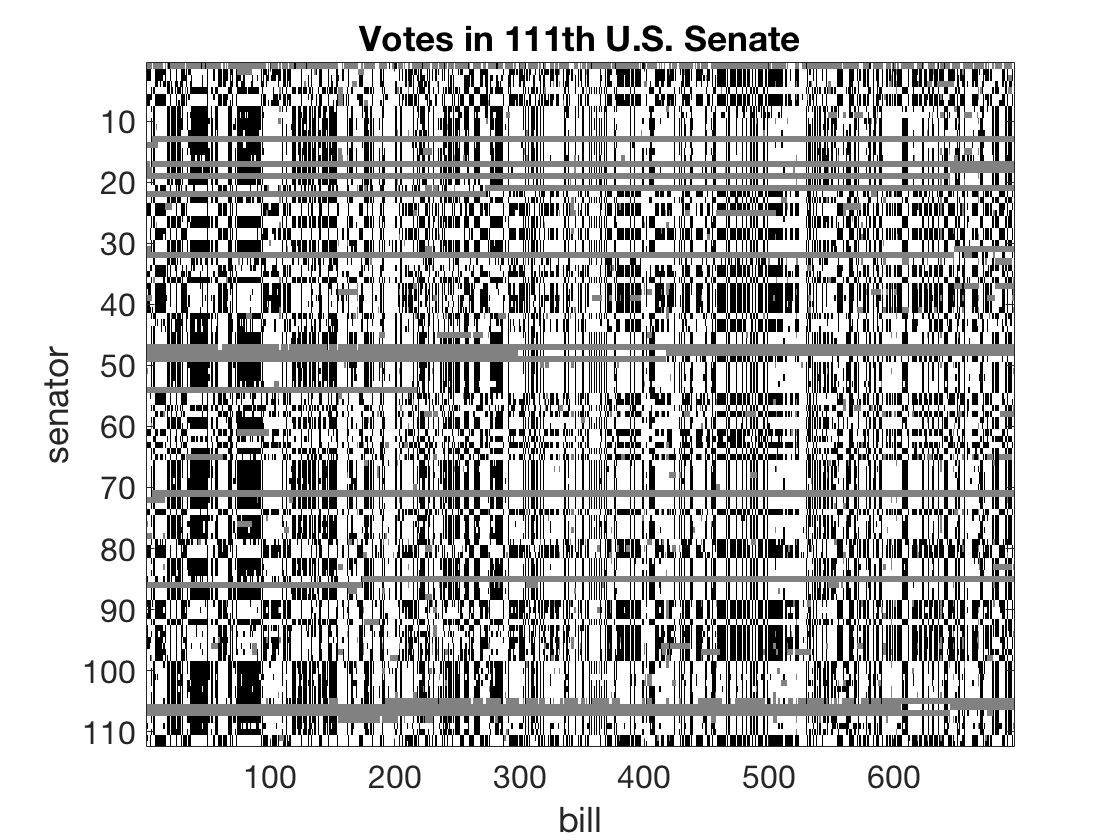

imagesc(A)
colormap gray
title('Votes in 111th U.S. Senate')   % ignore this line
ylabel('senator'), xlabel('bill')    % ignore this line

We use singular value ``energy'' to quantify the decay rate of the values. 

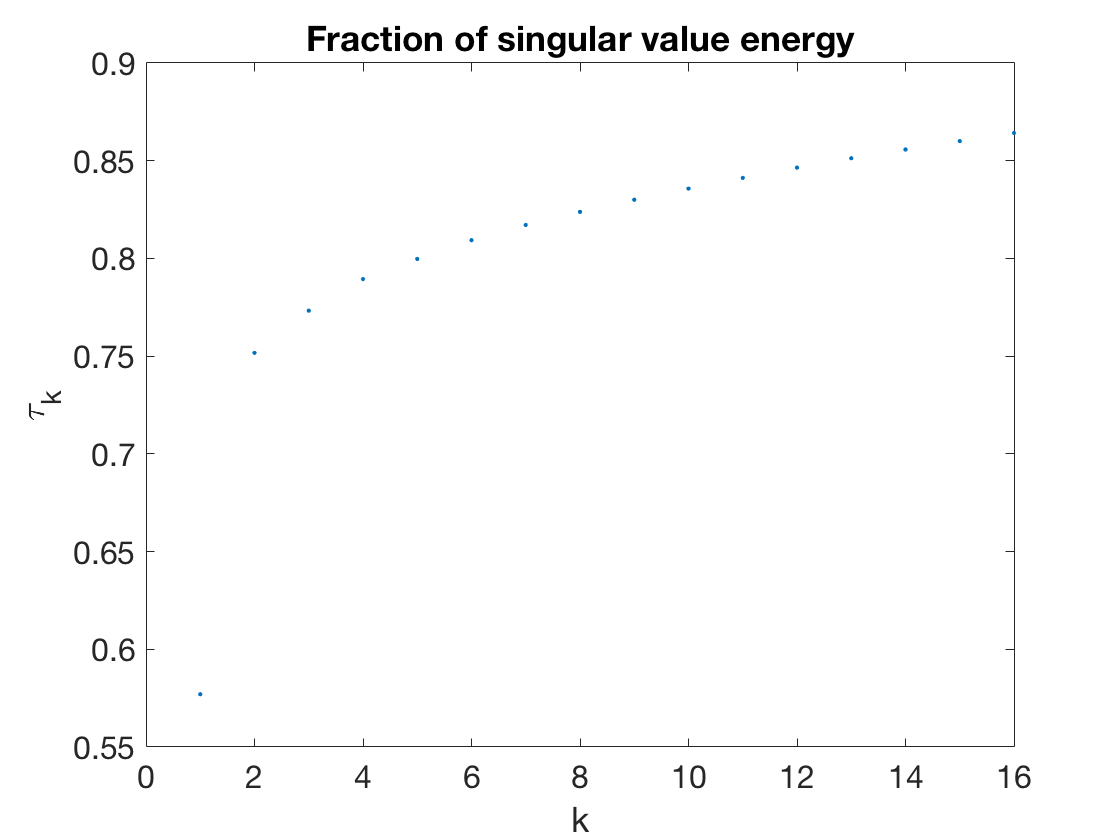

[U,S,V] = svd(A);
sigma = diag(S);
tau = cumsum(sigma.^2) / sum(sigma.^2);
plot(tau(1:16),'.')
xlabel('k'), ylabel('\tau_k')  % ignore this line
title('Fraction of singular value energy')     % ignore this line

The first and second singular triples contain about 58% and 17% respectively of the energy of the matrix. All others have far less effect, suggesting that the information is primarily two-dimensional. The first left and right singular vectors also contain interesting structure.

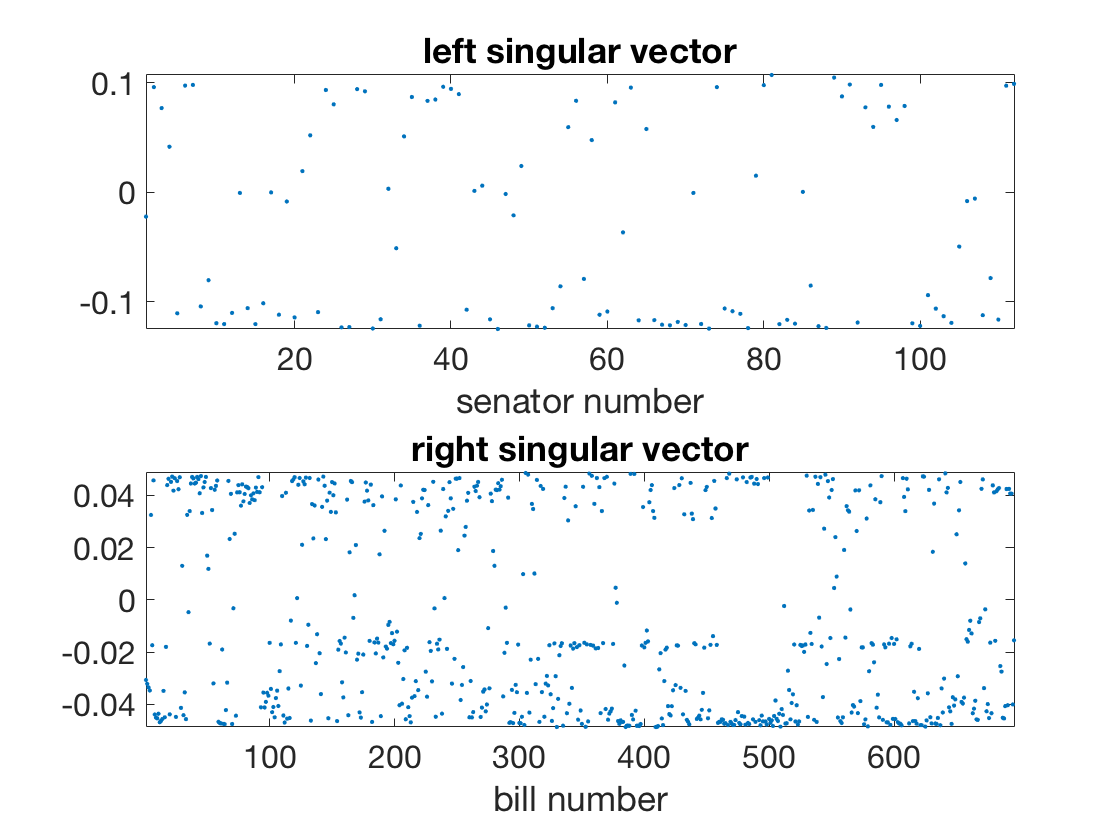

subplot(211), plot(U(:,1),'.')
axis tight  % ignore this line
xlabel('senator number'), title('left singular vector')  % ignore this line
subplot(212), plot(V(:,1),'.')
axis tight  % ignore this line
xlabel('bill number'), title('right singular vector')  % ignore this line

Both vectors have values greatly clustered near $\pm C$ for a constant $C$. These can be roughly interpreted as how partisan a particular senator or bill was, and for which political party. 

Projecting the senators' vectors into the first two $\mathbf{V}$-coordinates gives a particularly nice way to reduce them to two dimensions. Political scientists label these dimensions ``partisanship'' and ``bipartisanship.'' Here we color them by actual party affiliation (also given in the data file): red for Republican, blue for Democrat, and black for independent. 

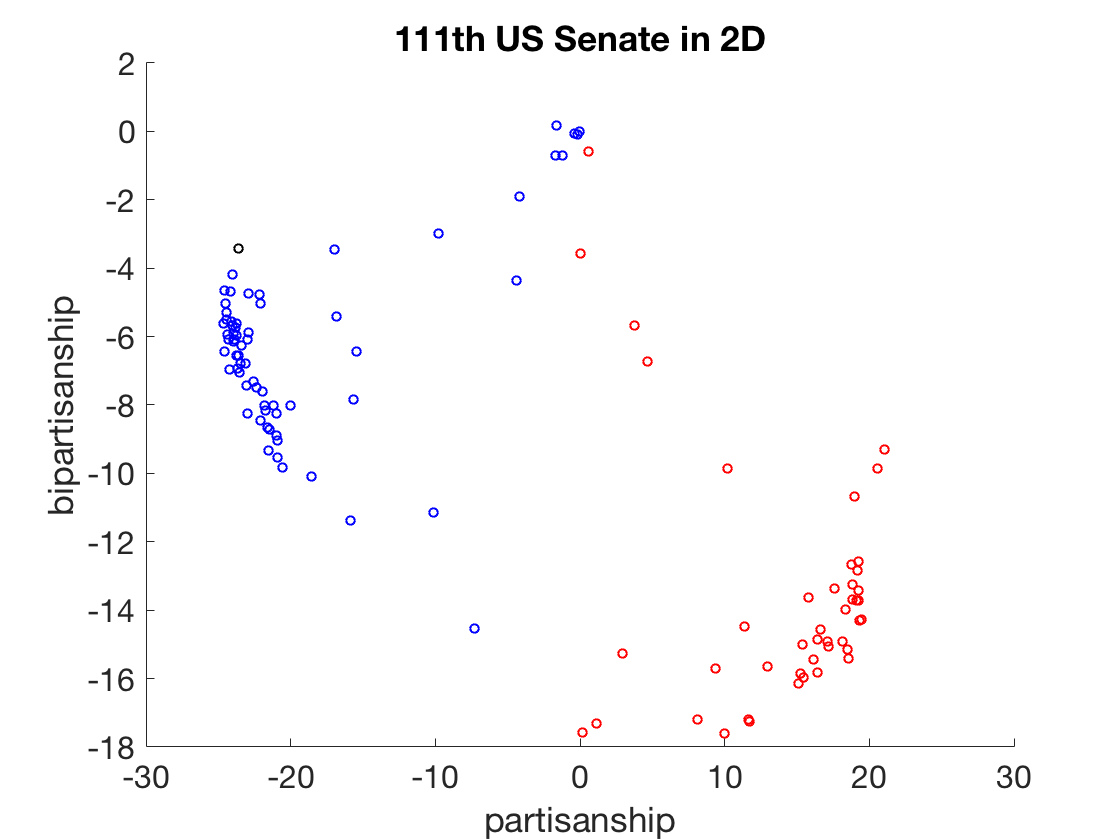

clf
x1 = V(:,1)'*A';   x2 = V(:,2)'*A'; 
scatter(x1(Dem),x2(Dem),20,'b'),  hold on
scatter(x1(Rep),x2(Rep),20,'r')
scatter(x1(Ind),x2(Ind),20,'k')
xlabel('partisanship'),  ylabel('bipartisanship')  % ignore this line
title('111th US Senate in 2D')